This demo is the matlab livescript that explaining how we mapped the vessel patterns onto the 3D brain surface data. Expected run time of this demo is 5 min.

First, let's see one of the brain surface data which we used for this demo.

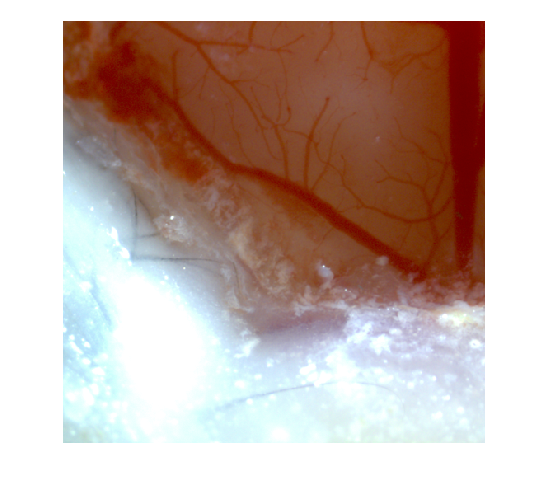

tic;
addpath(genpath('Functions'));
addpath(genpath('Data'));
img = imread('Data/demo/raw/standard45.tif');
figure;
imshow(img);

When we used the SA-UNet on this image, the result is like this:

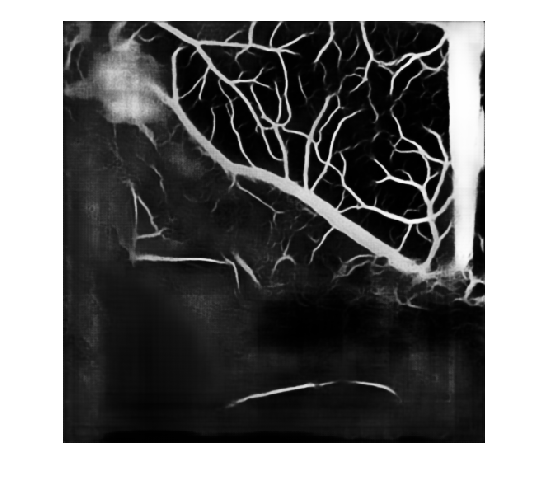

mask = imread('Data/demo/masks/standard45.png');
figure;
imshow(mask);

Next, run "AutoStitch" and select all the images in "Data/demo/masks/". "AutoStitch" is a standalone application that is available only on Windows, so we prepared the stitched image in 'Data/demo'.

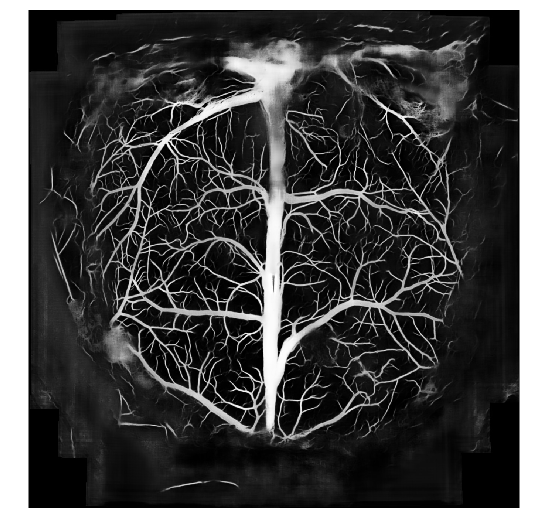

pano = rgb2gray(imread('Data/demo/pano.jpg'));
figure;
imshow(pano);

Also, a brain surface data is prepared. Blue scatter is the measured surface of the mouse brain and the red points are image aquisition points where the images stored in 'raw' were captured.

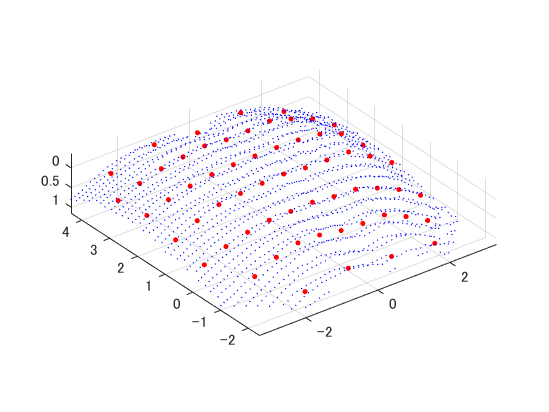

surf_data = importdata("Data/demo/surface.mat");
init_grid = importdata("Data/demo/init_grid.mat");
fig = figure;
scatter3(surf_data(:,2),surf_data(:,3),surf_data(:,1),1,'b','filled');
hold on;
scatter3(init_grid(:,2),init_grid(:,3),init_grid(:,1),10,'r','filled');
axis equal
fig.Children.ZAxis.Direction = 'reverse';

Now, let's get the transformation between the 3D data and the 2D image.


ソルバーが途中で停止しました。

fmincon は反復制限、options.options.MaxIterations = 2.000000e+00 
を超過したため、停止しました。


ソルバーが途中で停止しました。

fmincon は反復制限、options.options.MaxIterations = 2.000000e+00 
を超過したため、停止しました。


ソルバーが途中で停止しました。

fmincon は反復制限、options.options.MaxIterations = 2.000000e+00 
を超過したため、停止しました。


ソルバーが途中で停止しました。

fmincon は反復制限、options.options.MaxIterations = 2.000000e+00 
を超過したため、停止しました。


<a 

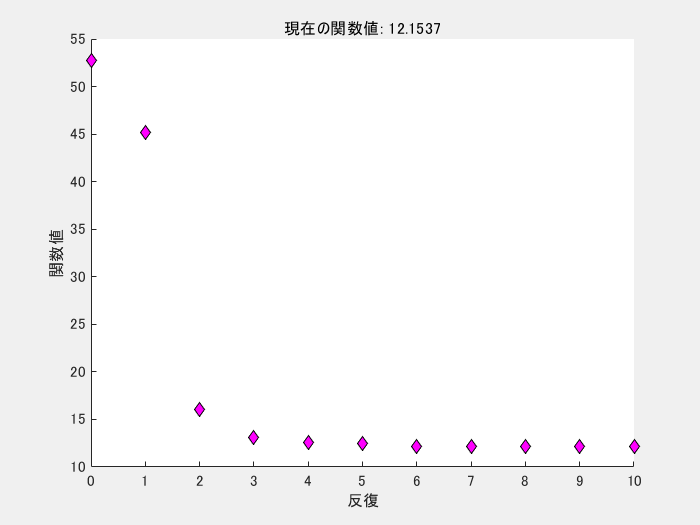


局所的最小値の可能性があります。制約が満たされました。

目的関数の予測された変化が関数の許容誤差値未満で、
制約が制約の許容誤差値の範囲内で満たされているため、
fmincon は停止しました。

<停止条件の詳細>


bregma = importdata("Data/demo/bregma.mat");
resize_scale = importdata("Data/demo/resize_scale.mat");
figsize = importdata("Data/demo/figsize.mat");
maskc = zeros(figsize,figsize,size(init_grid,1)+1,'uint8');
cropsize_for_stitch = 1024;
dbregma = bregma-[4024/2,3036/2];
for i = 0:size(init_grid,1)
    vidimage = imresize(imread(strcat('Data/demo/masks/standard',num2str(i),'.png')),resize_scale);
    if i == 0
            maskbregma = imcrop(vidimage,[size(vidimage,2)/2-cropsize_for_stitch/2,size(vidimage,1)/2-cropsize_for_stitch/2,cropsize_for_stitch-1,cropsize_for_stitch-1]);
            maskc(:,:,i+1) = imcrop(vidimage,[size(vidimage,2)/2-figsize/2,size(vidimage,1)/2-figsize/2,figsize-1,figsize-1]);
    else
        mc = imcrop(vidimage,[size(vidimage,2)/2-figsize/2,size(vidimage,1)/2-figsize/2,figsize-1,figsize-1]);
        maskc(:,:,i+1) = mc;
    end
end

[targetonfig,x_fig,tform_fig,tform_fig_inv,BregmasOnPano,errorIdx] = RotationMethod(pano,maskc,init_grid); 

figure;
e_surf_camera = [surf_data(:,1)-x_fig(1),surf_data(:,2),surf_data(:,3)];
theta = deg2rad(x_fig(2));
u = deg2rad(x_fig(3));
rotX = [1 0 0;0 cos(theta) sin(theta);0 -sin(theta) cos(theta)];
trans = [0, 0, 0];
rotY = [cos(u) 0 sin(u);0 1 0;-sin(u) 0 cos(u)];

rotZ = eye(3);
tform = rigid3d(rotX*rotY*rotZ,trans);
ptCloudOut = pctransform(pointCloud(e_surf_camera),tform);
e_surf_camera = ptCloudOut.Location;

F_camera = scatteredInterpolant(e_surf_camera(:,2),e_surf_camera(:,3),e_surf_camera(:,1));

%%% OUTPUT %%%
% Function object to convert the coordinates on the stitched image to those
% on 3D surface point clouds.
F2S = @(x) Fig2SurfFnc(x_fig,x,tform_fig_inv,F_camera);
% Function object to convert the coordinates on 3D surface point clouds
% to those on the stitched image.
S2F = @(x) Surf2FigFnc(x_fig,x,tform_fig);

The red points represent image aquisition points.

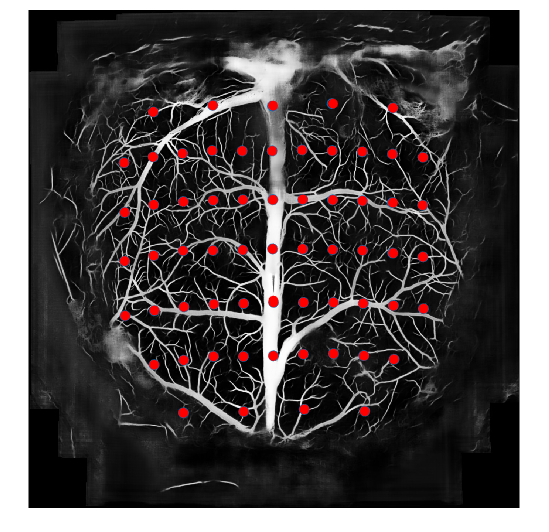

figure;
imshow(pano);
hold on
scatter(targetonfig(:,1),targetonfig(:,2));
hold on
scatter(BregmasOnPano(:,1),BregmasOnPano(:,2),'r','filled');

Next, let's decide the area where the injections were performed. By dragging and dropping, you can define the corner of the injection area.

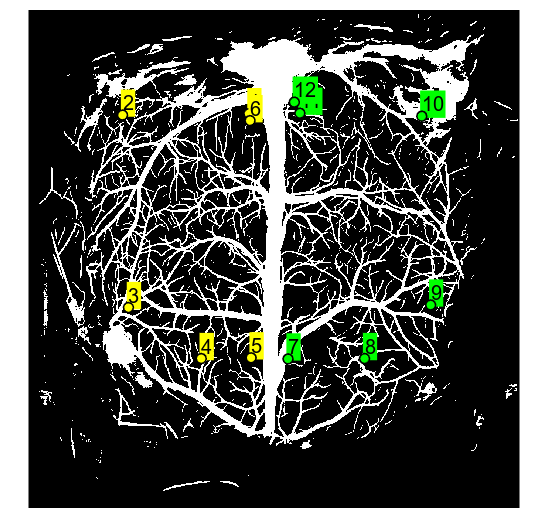

params = importdata("Data/params_mouse.mat");
global boundary
boundary = params.boundary;
figure;
imshow(mask_p);
roi_b = cell(size(boundary,1),1);
for i = 1:size(boundary,1)
    if i < 7
        roi_b{i} = images.roi.Point(gca,'Position',boundary(i,:),'Color','y');
    else
        roi_b{i} = images.roi.Point(gca,'Position',boundary(i,:),'Color','g');
    end
    roi_b{i}.Label = num2str(i);
    addlistener(roi_b{i},'ROIMoved',@getroiposEvent_boundary);
end

Finally, we run the injection site arranging algorithm.

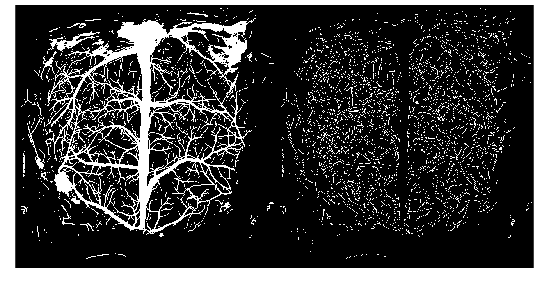

stop
stop
stop
stop
stop
stop
stop
stop
stop
stop
stop
stop


stop
stop
stop
stop
stop
stop
stop
stop
stop
stop
stop
stop


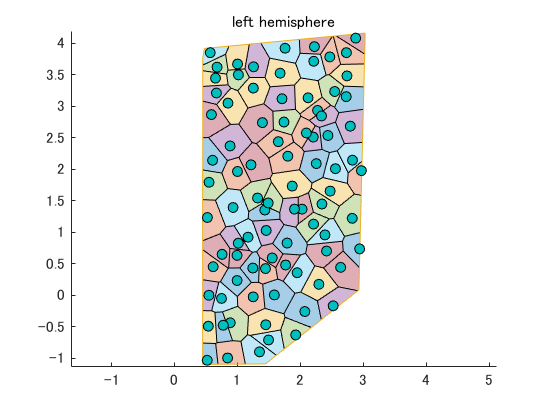

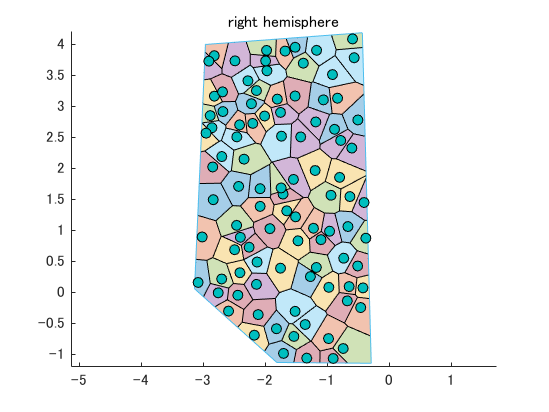

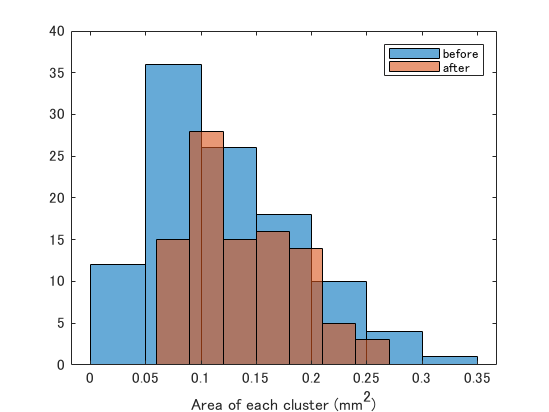

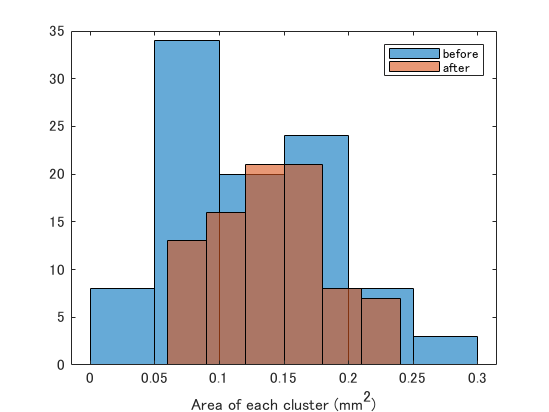

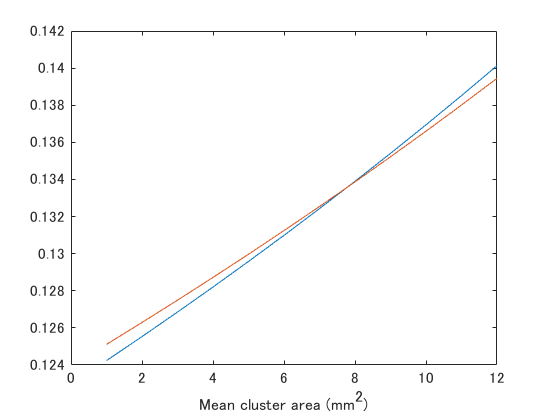

% Calculate the distance between vessels and non-vessels.
%%%%%%%%% Parameters for injection plannning %%%%%%%%%%%%%%

targetlen = 0.4; % Distance between injection sites(mm)
distlimit = 0.065; % Safe margin from the vessels(mm)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

result = CulcVesselDistMat(mask_p,boundary,F2S);

target = OptimLocate(result,boundary,targetlen,distlimit,F2S);

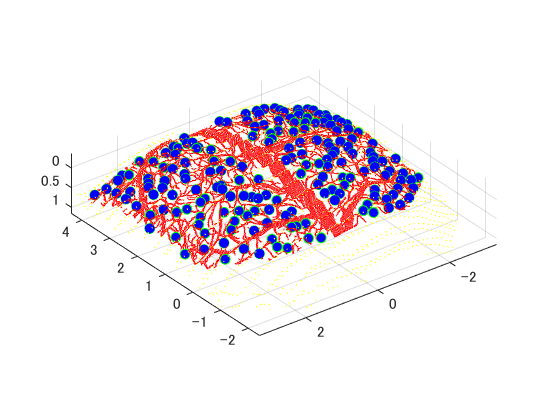


targetonfig = S2F(target);
global targetonfig_new
targetonfig_new = targetonfig;
% Check the targetonfig_new 

target_new = F2S(targetonfig_new);

[yv,xv] = find(mask_p);
[k_v,~] = convhull(boundary);
[in_v,on_v] = inpolygon(xv,yv,boundary(k_v,1),boundary(k_v,2));
VesselsOnFig = [xv(in_v|on_v),yv(in_v|on_v)];
vesselsOnSurf = F2S(VesselsOnFig);

figure;
scatter3(surf_L_rmd(:,2),surf_L_rmd(:,3),surf_L_rmd(:,1),1,'y','filled');
hold on
scatter3(target_new(:,2),target_new(:,3),target_new(:,1),'b','filled');
hold on
scatter3(target(:,2),target(:,3),target(:,1),'g');
hold on
scatter3(vesselsOnSurf(:,2),vesselsOnSurf(:,3),vesselsOnSurf(:,1),0.1,'r');
set(gca,'XDir','reverse');
set(gca,'ZDir','reverse');
axis equal

We also provide the final human check and validation process here.

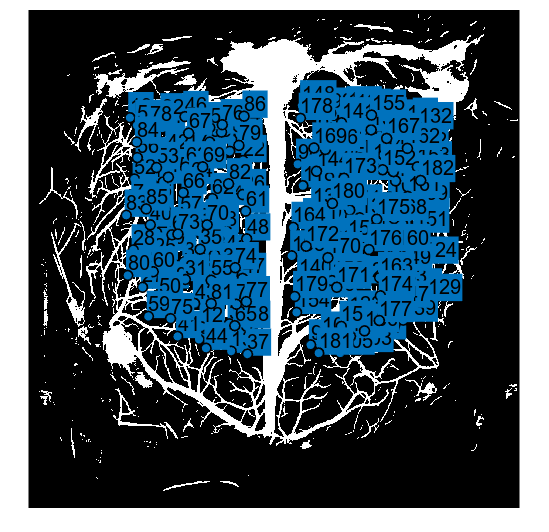

% Interactively change the position of ROI
figure;
%imshow(pano);
imshow(mask_p);
roi = cell(size(targetonfig_new,1),1);
for i = 1:size(targetonfig_new,1)
    roi{i} = images.roi.Point(gca,'Position',targetonfig_new(i,:));
    roi{i}.Label = num2str(i);
    addlistener(roi{i},'ROIMoved',@getroiposEvent);
end

toc

経過時間は 356.662538 秒です。


function getroiposEvent(src,evt)
global targetonfig_new
evname = evt.EventName;
    switch(evname)
        case{'ROIMoved'}
            disp(['ROI moved Previous Position: ' mat2str(evt.PreviousPosition)]);
            disp(['ROI moved Current Position: ' mat2str(evt.CurrentPosition)]);
            disp(evt.Source)
            targetonfig_new(cast(str2double(evt.Source.Label),'uint8'),:) = evt.CurrentPosition;
    end
end

function getroiposEvent_boundary(src,evt)
global boundary
evname = evt.EventName;
    switch(evname)
        case{'ROIMoved'}
            disp(['ROI moved Previous Position: ' mat2str(evt.PreviousPosition)]);
            disp(['ROI moved Current Position: ' mat2str(evt.CurrentPosition)]);
            disp(evt.Source)
            boundary(cast(str2double(evt.Source.Label),'uint8'),:) = evt.CurrentPosition;
    end
end

